% esempio sistema del tipo 1
% errore di posizione
clear, close all
syms t
 n = 4;
 d = [1 6 5 4];
 G0 = tf(n,d)

G0 =
 
            4
  ---------------------
  s^3 + 6 s^2 + 5 s + 4
 
Continuous-time transfer function.
Model Properties


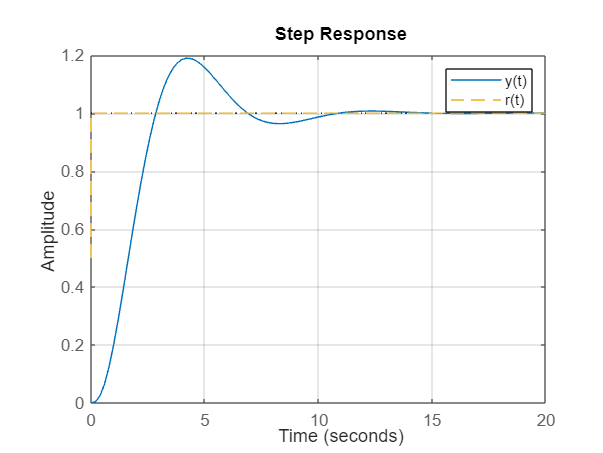

 figure(1)
 step(G0, 20), grid, hold on
 fplot(heaviside(t),'--'), legend('y(t)','r(t)')

 % a regime l'uscita segue l'ingresso
 
 % errore di velocità
 s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


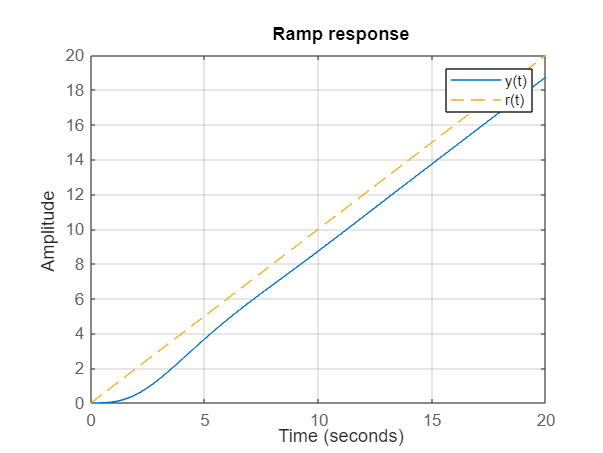

 figure(2)
 step(G0/s, 20), grid, hold on, title('Ramp response')
 fplot(t*heaviside(t),'--'), legend('y(t)','r(t)')

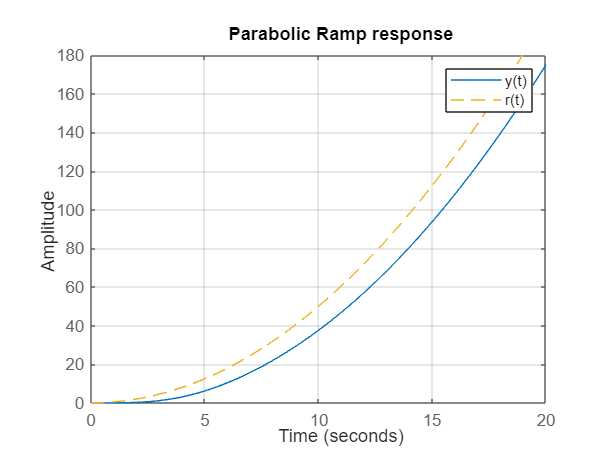

 
 %  errore di accelerazione 
 figure(3)
 step(G0/s^2, 20), grid, hold on, title('Parabolic Ramp response')
 fplot(t^2/2*heaviside(t),'--'), legend('y(t)','r(t)')